px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5

stopien = 5

W = polyfit(px, py, stopien)

W =    -0.0000    0.0000    0.0011   -0.0000         0    0.0000


fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x

fx = function_handle with value:
    @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x


% -8
[x1,y1,z1] = ekspansion_method(-8, 0.1, fx, 1.5 ,10000)

x1 = -5.4371

y1 = -2.2335

z1 = 10

% -0.5
[x2,y2,z2] = ekspansion_method(-0.5, 0.1, fx, 1.5 ,10000)

x2 = -0.2750

y2 = 0.0063

z2 = 4

% -1
[x3,y3,z3] = ekspansion_method(1, 0.1, fx, 1.5 ,10000)

x3 = -0.7086

y3 = 0.2406

z3 = 7

% 8
[x4,y4,z4] = ekspansion_method(8, 0.1, fx, 1.5 ,10000)

x4 = 20.9746

y4 = 37.1929

z4 = 14


% -1
[x,y,z] = ekspansion_method(8, 0.1, fx, 1.5 ,10000)

x = 20.9746

y = 37.1929

z = 14

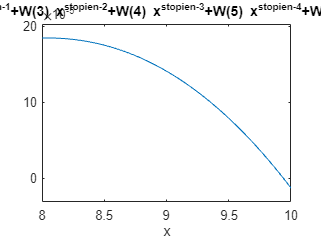


ezplot(fx,[8,10])